# Time evolution of the Schrodinger equation

## Localized potential & localized state

If there is something that lends itself to solve numerically the Schrodinger equation dependent on time this is the operator splitting technique.

Let's imagine to have an Hamiltonian given only by the kinetic term,  that is the one of the free particle


$$\hat{T} =-\frac{1}{2}\frac{\partial^2 }{\partial x^2 }=\frac{1}{2}\Delta$$


We already know how to diagonalize this finite operator, we can use the finite fourier transform in one of its three acceptions, but we need to discuss the boundary condition of the problem, in order to choose the right one. To do so we have to give a proper example.

We will discuss the time evolution of a localized state which collides against a double well potential barrier.

We define a dimension N for the space grid and a lattice spacing a

N = 2.24e3;

### Optimal lattice spacing

We impose the conservation of energy condition to find the optimal lattice spacing given the Double Well potential. We write the conservation equation 

$T_{\max } =V_{\max }$  where $V={\frac{\left(x^2 -{\textrm{shift}\;}^2 \right)}{24}}^2$and $T=\frac{1}{2}\frac{k_{\max }^2 }{a^2 }$; if we substitute the expressions for $k_{\max }$ and $x_{\max }$ 


$$k = \frac{\pi}{N+1}n\;\;\;\;q=-\frac{N-1}{2},...,\frac{N-1}{2}\;\; and \;\;x_{max}=q_{max}=\frac{N-1}{2}$$


the conservation equation becomes the 6th grade equation in $a$


$${\left(N\right)}^4 \frac{1}{24}a^{6\;\;} -2\cdot {\textrm{shift}}^2 {\cdot N}^2 \frac{1}{24}a^4 +\frac{{\textrm{shift}}^4 }{24}a^2 -\pi^2 {\left(\frac{N}{N+1}\right)}^2 =0$$


 where $\textrm{shift}=\frac{\textrm{length}\left(x\right)}{200}$

and if we solve it for $a$ we will find the six roots shown in the ${\textrm{Wolfram}}^{\textrm{TM}}$ plot

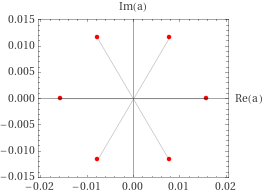

the two real roots are $a=\pm 0\ldotp 015779$; we will choose the positive root as optimal lattice spacing.


a=0.0150984;
%a=0.0121775;
%H=hamiltonian1D(N,a,V,'DBC')
x = -(N-1)/2:(N-1)/2; 
x = a*x';
shift = length(x)/200; %make the shift of the potential dependent 
                      % from the size of the lattice
V= @(x) (x.^2-shift^2).^2/24;
%optimal lattice spacing conserving energy
plot(x,V(x),'.-');
title('Double Well potential')

With this approach we obtain a lattice spacing which depends on the shift of the double well. Since the number of points are fixed we have to find the best shift factor for this particular choice of the lattice spacing; Such a shift will allow us to obtain a pronounced double bell potential, like in figure 2 (we choose that a right shift value might be $\approx \frac{\;\textrm{length}\left(x\right)}{200}$).

### Localized state with initial momentum $\hat{k_0 }$

k_0 = 10;     % Initial Momentum of a localized state 
             % we need to assing an initial momentum to the state by
             % multiplying for the phase exp(i*k_0*x)
            %it fixes a velocity for the wave package (k=2pi/w)

sigma = 0.1;   % initial Gaussian width 
psi0 = exp(1i*k_0*x).*exp(-(x+15.25).^2/sigma^2/2); %localized state with momentum
psi0 = psi0/norm(psi0);
psi = psi0;   

s=3.5e4;  
hold on 
%plot(x,s*abs(psi).^2,'.-')

We will use the scale factor $s$ to plot the state ; the scale of the problem is actually fixed by the size of the double well as we have just seen from the optimal lattice spacing equation.

The time evolution of this experiment leads to the collision of the state (which is moving to the right due to its positive $k_0$) on the barrier and due to the reflection coefficient of the barrier we know that "part" of this wave function is rejected to the left. Therefore the lattice representing the space must not have classic periodic boundary conditions. Actually in the case of PBC the parts of the wavefunction reaching the edges of the finite volume would interfere with each other or at least propagate in the rest of the volume. As we need a space with boundary conditions that zero out the wavefunctions at the edges, we choose the Dirichlet boundary conditions, yet discussed in the Finite Fourier tranform section;

We can define $k_n =\frac{\pi }{N+1}n\;\;\;\;n=1\ldotp \ldotp \ldotp N$  and the kinetc enegy written in term of the momentum $\frac{1}{2a^2 }k^2 =T$

k = (pi/(N+1))*(1:N)';  % momentum 
kinE = (k/a).^2/2;  %Kinetic energy

%single time step size
tau = 0.001;
%time step number   % total time of the simulation is t=10s 
nt = 1e3;

### Operator splitting

We write the approximation for the application of Time evolution operator as   $\hat{U} \;\Psi =e^{-\textrm{iV}\frac{\tau }{2}\;} \;F^{-1} \left(e^{-i\;\frac{k^2 }{2}} \;F\left(e^{-\textrm{iV}\frac{\tau }{2}} \;\Psi \right)\;\;\right)\;$

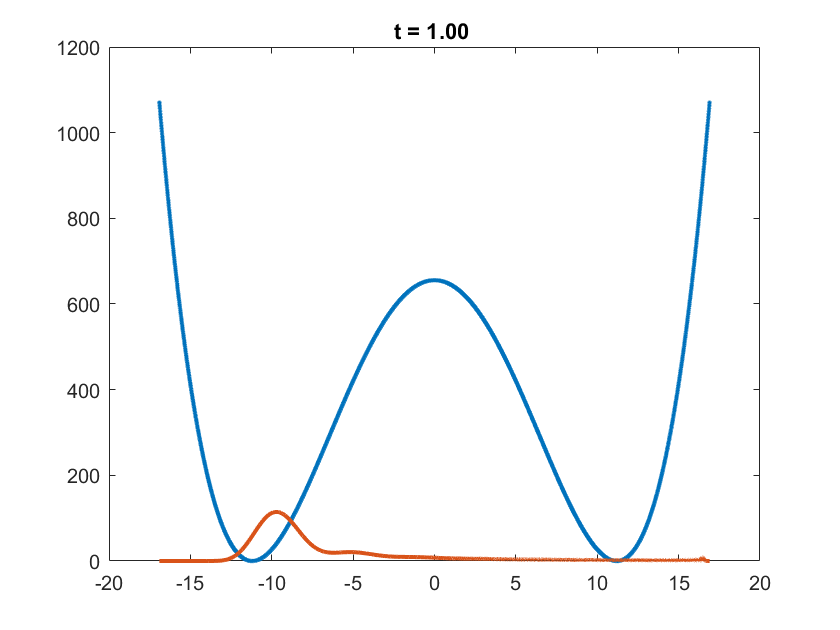

if exist('hf','var') && isgraphics(hf)
    hf.YData = s*abs(psi).^2;        %plot dello stato sul grafico
else
    hf = plot(x,s*abs(psi).^2,'linewidth',2);
end
ht = title(sprintf('t = %-5.2f',0));
tic;
for j=1:nt
    psi = exp(-1i*V(x)*tau/2).*psi;
    psi = sinft(exp(-1i*kinE*tau).*sinft(psi));
    psi = exp(-1i*V(x)*tau/2).*psi;
    if mod(j,5) == 0
        hf.YData = s*abs(psi).^2;
        ht.String = sprintf('t = %-5.2f',j*tau);
        drawnow;
    end
end

toc;

Elapsed time is 14.341348 seconds.


### Classical Energy & Tunnel effect

The state used in the simulation  has a starting classic energy at 50.0525; the wave packet has its initial position in a region of space in which the potential is decreasing, toward its first knot ($x\approx 11$), so the state can pass through the barrier reaching the central region. Once there the state crash against a potential barrier which has an higher energy than the initial state. The state must come back, descending again the potential gradient towards the first minimum. From a classical point of view, a wave packet with fixed average energy has components with higher energy than the averge, so even in a classical framework we expect the portion of the packet that crosses the barrier to be non-zero. However in the quantum mechanical context we expect the fraction of the packet that crosses the barrier to be greater. We prove it by calculating the probability of the state of reaching the region x>0 by according to both points of view.

First we calculate the average energy of the state 

classicE= k_0^2/(2) + V(11.25) %almost the whole energy is due to kinE

classicE = 50.0525

V_0=V(0) %energy in the centre of the barrier (x=0)

V_0 = 655.6331

### $\Psi$ decomposition over the base of $H$

The classical probability of crossing the barrier is calculated by projecting the state on the basis of the Hamiltonian, interpreting the state as a gaussian distribution of energy

W=@(x)((a.*x).^2 - shift^2).^2/24;
[H,~,Htri] = hamiltonian1D_mod(N,a,V,'DBC');
[Phi,E] = eig(H);
E=diag(E);

projection_Psi = abs(Phi'*psi0).^2 ;
disp('classic trasmission probability')

classic trasmission probability


P_classic=sum(projection_Psi(E>V_0))^2

P_classic = 0.0115

### Quantum tunneling measurement

According to quantum mechanics the probability for the wave packet to cross the potential hill (in $x=0$) is obtained as the probability of the time evolution of the state 

%plot(x,psi)
disp('probability of crossing the state')

probability of crossing the state


P_quant=norm(psi(x>0))^2

P_quant = 0.1045

Let's verify that Unitariety is conserved after the transformation

norm(psi)

ans = 1.0000

As we can see the probability of crossing the barrier  in a classical framework is way lower than the quantum-mechanics probability, gained as the integral of the intern product between $\Psi \;\textrm{and}\;\Psi^*$.

disp('Tunnel effect')

Tunnel effect


P_quant-P_classic

ans = 0.0930

In this simulation on a brief interval of time, small enough to interrupt the it before portions of the state begin to interfeere with each other.

### Time evolution - Direct method

The direct method to compute the time evolution of a state consists in the direct product   $U\left(\tau \right)|\Psi \rangle =e^{-\textrm{iH}\tau \;} |\Psi \rangle$

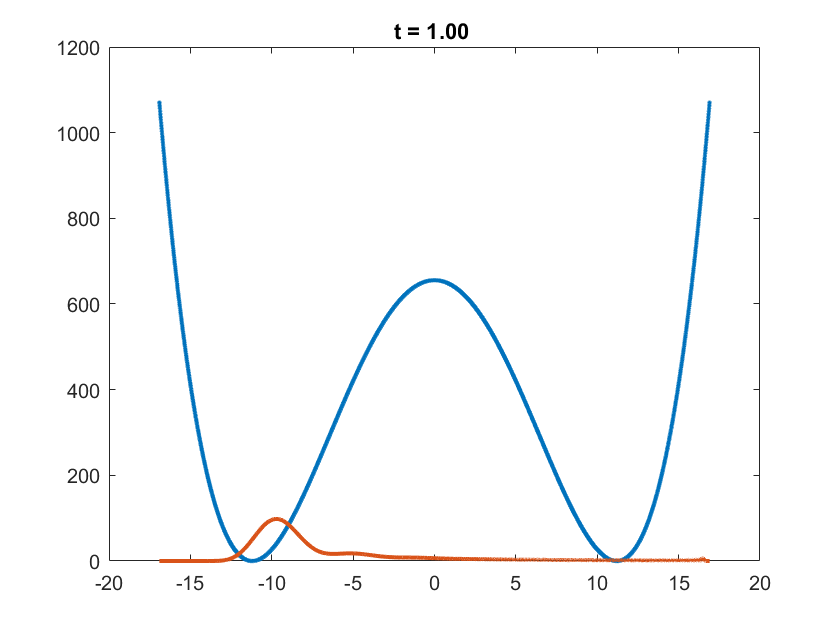

s=3e4; %reducing plot scale factor for the state 
Chi = psi0;
U = expm(-1i*H*tau);
tic;
for j=1:nt
    Chi = U*Chi; 
    if mod(j,5) == 0
        hf.YData = s*abs(Chi).^2;
        ht.String = sprintf('t = %-5.2f',j*tau);
        drawnow;
    end
end

toc;

Elapsed time is 19.547976 seconds.


### Accuracy

disp('complex Chi square between the two methods')

complex Chi square between the two methods


disp(sum((Chi-psi).^2)/length(psi));

   2.2098e-13 + 7.5930e-13i



It is clear that the operator splitting technique is faster than the direct method.

Now we can compare the probability of quantum tunneling with both methods to check the accuracy of operator splitting.

norm(Chi)^2-norm(psi)^2

ans = -4.8850e-14

 We find out that the difference between the two results is negligible: operator splitting is a valid algorithm to solve the time dependent Schrodinger equation.